Definizione del **numeratore** e del **denominatore** della **FdT**.

num = 10;
den = [1 1];

sys = tf(num,den)


sys =
 
   10
  -----
  s + 1
 
Continuous-time transfer function.
Model Properties


Calcolo dei **poli** del sistema dinamico.

pole(sys)

ans = -1

Tracciamento del **diagramma di Bode**.

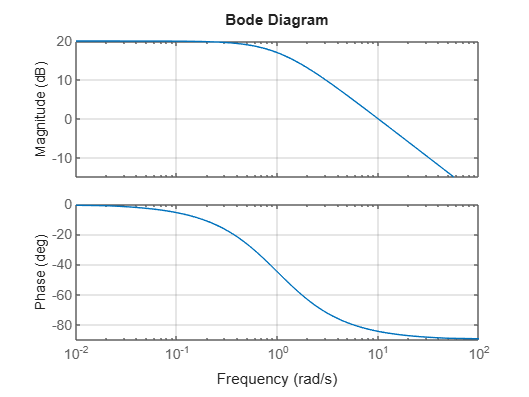

bode(sys);
grid on

Calcolo del **Margine di Guadagno** e** di Fase **della funzione L(s) = 10/(s + 1)**.**

- **Margine di Guadagno**: Il modulo vale ∣L(j9.95)∣| = è 1 --> 20log10(1) = 0 dB.                                                                                            Il margine di guadagno si calcola alla frequenza di incrocio di fase ωpc, che è la frequenza alla quale la fase è −180° --> K = 1/∣L(jωpc)∣|. Il margine di guadagno è **infinito**, poiché il diagramma delle fasi non interseca mai l’asse a −180°.

- **Margine di Fase**: La fase a 9.95 [rad/s] è di circa 84,3° --> atan(9.95/1).                                                             Il margine di fase è dato da 180°−∣ϕ∣ = 180°−84.3°=95.7°

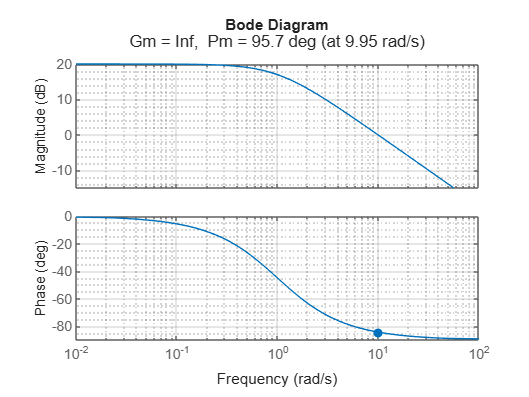

margin(sys)
grid on
grid minor